 %%%%% .
clc
clear all
close all

%%%%%%%%%% Experimental data 10,0
%%yield strain
ExpYs300K= [0.18132674 0.180902356 0.183134465 0.184052545 0.18365482 0.188517946 0.188998017]';
ExpYs800K= [0.14360818 0.155900875 0.161205565 0.161244665 0.16654817 0.16878087 0.168820562]';
ExpYs1600K= [0.109396063 0.108531893 0.110765186 0.118262292 0.131022025 0.13632553 0.139434842]';
ExpYs2400K= [0.0602863 0.068220822 0.076155345 0.086723255]';
%%%%strain rate
ExpSr300K=[2.53042e-05 3.23437e-05 6.35671e-05 0.000128792 0.000260872 0.000507762 0.001039251]';
ExpSr800K= [2.56287e-05 3.15269e-05 6.45907e-05 0.000126887 0.000254695 0.000505716 0.001003686]';
ExpSr1600K= [2.49345e-05 3.12228e-05 6.26328e-05 0.00012707 0.00025545 0.000512754 0.001007929]';
ExpSr2400K= [3.1234e-05 6.20899e-05 0.000123428 0.000253145]';
%%%%%%
Srate = [1 0.75 0.5 0.25]'*1e-3 ;
Ys_100= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Ys_100.txt','r');
Sut_100= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (10,0)-60\Sut_100.txt','r');
Ys_200= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Ys_200.txt','r');
Sut_200= fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\SWCNT (20,0)-60\Sut_200.txt','r');
Ys_MWCNT =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Ys_MWCNT.txt','r');
Sut_MWCNT =fopen('C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\MWCNT (20,0,63.9),(10,0,55.2)\Sut_MWCNT.txt','r');

Ys100 = [cell2mat(textscan(Ys_100,'%f%f%f%f'))] %strain

Ys100 =     0.1826    0.1707    0.1258    0.0995
    0.1899    0.1636    0.1318    0.0834
    0.1890    0.1709    0.1343    0.0924
    0.1931    0.1621    0.1167    0.0665


Ys200 = [cell2mat(textscan(Ys_200,'%f%f%f%f'))]     %300K,800k,1600k,2400k

Ys200 =     0.2015    0.1812    0.1240    0.1040
    0.1972    0.1895    0.1312    0.1071
    0.2058    0.1800    0.1416    0.1072
    0.2006    0.1722    0.1056    0.1007


Ysmwcnt = [cell2mat(textscan(Ys_MWCNT,'%f%f%f%f'))]    %in

Ysmwcnt =     0.1856    0.1609    0.1228    0.1060
    0.1847    0.1537    0.1270    0.1012
    0.1790    0.1527    0.1228    0.1040
    0.1858    0.1497    0.1186    0.0924


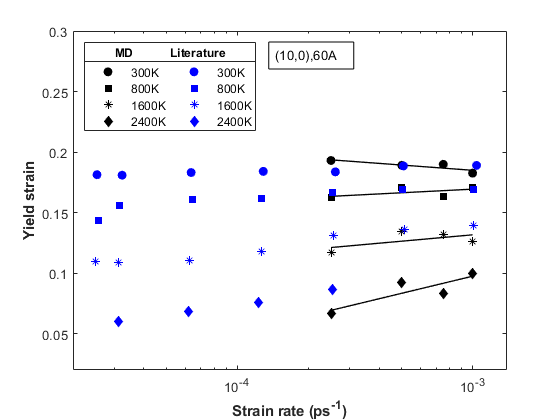

fclose(Ys_200);fclose(Ys_MWCNT);fclose(Ys_100);

C1_300K= Ys100(1:4,1);
C1_800K= Ys100(1:4,2);
C1_1600K= Ys100(1:4,3);
C1_2400K= Ys100(1:4,4);
C2_300K= Ys200(1:4,1);
C2_800K= Ys200(1:4,2);
C2_1600K= Ys200(1:4,3);
C2_2400K= Ys200(1:4,4);
MW_300K= Ysmwcnt(1:4,1);
MW_800K= Ysmwcnt(1:4,2);
MW_1600K= Ysmwcnt(1:4,3);
MW_2400K= Ysmwcnt(1:4,4);

%scnt 10,0 simulation
% C1_300K = [0.196 0.20 0.189 0.194]'   ;    %YIELD STRAIN
% C1_800K=[0.16 0.176 0.171 0.167]';
% C1_1600K=[0.127 0.1334 0.1375 0.1214 ]';
% C1_2400K=[0.1099 0.105 0.101 0.073]';


f1 = polyfit(log(Srate),C1_300K,1); fitf1=polyval(f1,log(Srate));
f2 = polyfit(log(Srate),C1_800K,1); fitf2=polyval(f2,log(Srate));
f3 = polyfit(log(Srate),C1_1600K,1); fitf3=polyval(f3,log(Srate));
f4 = polyfit(log(Srate),C1_2400K,1); fitf4=polyval(f4,log(Srate));

figure(1)
semilogx(Srate,C1_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C1_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4,'-k','LineWidth',1); hold on

semilogx(ExpSr300K,ExpYs300K,'ob',"MarkerFaceColor","b"); hold on  % experimental data 10,0
semilogx(ExpSr800K,ExpYs800K,'sb',"MarkerFaceColor","b"); hold on
semilogx(ExpSr1600K,ExpYs1600K,'*b',"MarkerFaceColor","b"); hold on
semilogx(ExpSr2400K,ExpYs2400K,'db',"MarkerFaceColor","b"); hold on

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield strain',"FontWeight","bold")

lgd= legend('300K','800K','1600K','2400K','','','','','300K','800K','1600K','2400K','Location','northwest','NumColumns',2);
title(lgd,'MD           Literature') 
xlim([0.00002 0.0014])
ylim([0.02 0.3])
%grid on
annotation('textbox', [0.48, 0.8, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate_valid_100.jpg')
hold off

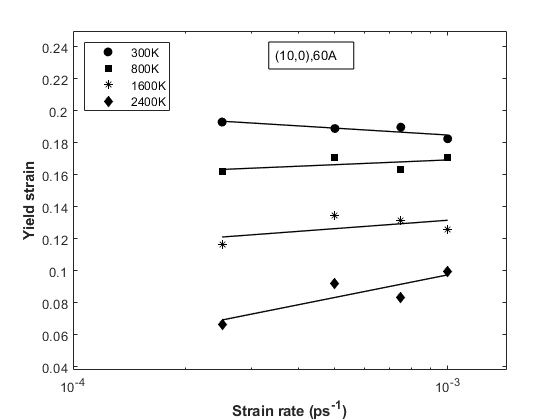

figure(3)
semilogx(Srate,C1_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C1_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4,'-k','LineWidth',1); hold on

xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield strain',"FontWeight","bold")

lgd= legend('300K','800K','1600K','2400K','Location','northwest','NumColumns',1);
%title(lgd,'MD           Literature') 
xlim([0.0001 0.00144])
ylim([0.038 0.25])
%grid on
annotation('textbox', [0.48, 0.8, 0.1, 0.1], 'String', "(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate_10060A.jpg')
hold off

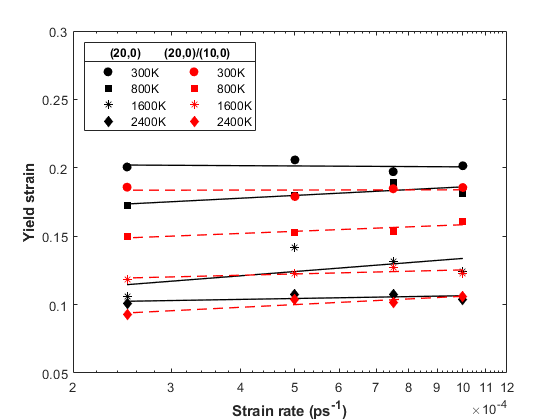

%%%%% cnt.20.0.60

%strain at temp 20,0,60
% C2_300K = [0.21 0.208 0.206 0.20]'   ;    %YIELD STRAIN
% C2_800K=[.1899 .189 .182 .18]';
% C2_1600K=[.1258 .131 .1415 .106]';
% C2_2400K=[.1095 .109 .1057 .09]';
% Srate = [1 0.75 0.5 0.25]'*1e-3 ;   
% %55swcnt20,0
f1h = polyfit(log(Srate),C2_300K,1); fitf1h=polyval(f1h,log(Srate));
f2h= polyfit(log(Srate),C2_800K,1); fitf2h=polyval(f2h,log(Srate));
f3h= polyfit(log(Srate),C2_1600K,1); fitf3h=polyval(f3h,log(Srate));
f4h= polyfit(log(Srate),C2_2400K,1); fitf4h=polyval(f4h,log(Srate));

%Mwcnt
% MW_300K = [.1858 .1847 .1789 .1858]'   ;    %YIELD STRAIN
% MW_800K=[.1609 .1537 .1564 .155]';
% MW_1600K=[.19 .198 .194 .195]';
% MW_2400K=[.18 .185 .183 .180]';
% %mwcnt....
f1m = polyfit(log(Srate),MW_300K,1); fitf1m=polyval(f1m,log(Srate));
f2m= polyfit(log(Srate),MW_800K,1); fitf2m=polyval(f2m,log(Srate));
f3m= polyfit(log(Srate),MW_1600K,1); fitf3m=polyval(f3m,log(Srate));
f4m= polyfit(log(Srate),MW_2400K,1); fitf4m=polyval(f4m,log(Srate));

%%% comparision  20,0 vs 20,0/10,0
figure(2)
semilogx(Srate,C2_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C2_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C2_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C2_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1h,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2h,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3h,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4h,'-k','LineWidth',1); hold on

semilogx(Srate,MW_300K,'or',"MarkerFaceColor","r"); hold on %%%simulat
semilogx(Srate,MW_800K,'sr',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_1600K,'*r',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_2400K,'dr',"MarkerFaceColor","r"); hold on

semilogx(Srate,fitf1m,'--r','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf3m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf4m,'--r','LineWidth',1); hold on


xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield strain',"FontWeight","bold")

lgd= legend('300K','800K','1600K','2400K','','','','','300K','800K','1600K','2400K','Location','northwest','NumColumns',2);
title(lgd,'(20,0)       (20,0)/(10,0)') 
xlim([0.0002 0.0012])
ylim([0.05 0.3])
%annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Syt_vs_Srate200100.jpg')
%grid on
hold off

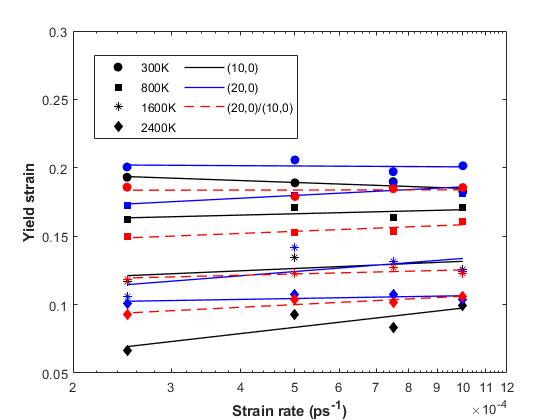

%%%% compa all
figure(4)

semilogx(Srate,C1_300K,'ok',"MarkerFaceColor","k"); hold on %%%simulat
semilogx(Srate,C1_800K,'sk',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_1600K,'*k',"MarkerFaceColor","k"); hold on
semilogx(Srate,C1_2400K,'dk',"MarkerFaceColor","k"); hold on

semilogx(Srate,fitf1,'-k','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2,'-k','LineWidth',1); hold on
semilogx(Srate,fitf3,'-k','LineWidth',1); hold on
semilogx(Srate,fitf4,'-k','LineWidth',1); hold on



%%% comparision  20,0 vs 20,0/10,0

semilogx(Srate,C2_300K,'ob',"MarkerFaceColor","b"); hold on %%%simulat
semilogx(Srate,C2_800K,'sb',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_1600K,'*b',"MarkerFaceColor","b"); hold on
semilogx(Srate,C2_2400K,'db',"MarkerFaceColor","b"); hold on

semilogx(Srate,fitf1h,'-b','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf3h,'-b','LineWidth',1); hold on
semilogx(Srate,fitf4h,'-b','LineWidth',1); hold on

semilogx(Srate,MW_300K,'or',"MarkerFaceColor","r"); hold on %%%simulat
semilogx(Srate,MW_800K,'sr',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_1600K,'*r',"MarkerFaceColor","r"); hold on
semilogx(Srate,MW_2400K,'dr',"MarkerFaceColor","r"); hold on

semilogx(Srate,fitf1m,'--r','LineWidth',1); hold on    % ploting trend line simulation
semilogx(Srate,fitf2m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf3m,'--r','LineWidth',1); hold on
semilogx(Srate,fitf4m,'--r','LineWidth',1); hold on


xlabel('Strain rate (ps^{-1})',"FontWeight","bold")
ylabel('Yield strain',"FontWeight","bold")

lgd= legend('300K','800K','1600K','2400K','','(10,0)','','','','','','','','(20,0)','','','','','','','','(20,0)/(10,0)','','','Position',[0.3 0.67 0.1 0.2],'NumColumns',2);
%title(lgd,'(20,0)       (20,0)/(10,0)') 
%title(lgd,'(20,0)       (20,0)/(10,0)') 
xlim([0.0002 0.0012])
ylim([0.05 0.3])
%annotation('textbox', [0.38, 0.8, 0.1, 0.1], 'String', "(20,0)/(10,0),60A",'FitBoxToText',"on")
saveas(gcf,'C:\Users\lenovo\OneDrive - IIT Delhi\NanoMechanics Project\Graphs\Ys_vs_SrateCompaAll.jpg')
%grid on
hold off